# Uncertain Observer Simulation

Author: Jonas Wagner

Date: 2021-12-14

clear
close all

### Simulation Setup

#### Siumulation Settings

% Simulation Timesteps
N = 100;

sysSelect = 4;
alphaSelect = 1;
% IC_Select = 

% Run Tests
testCtrb = false;
testObsv = false;
testK = false;
testL = false;

% Run Sim
runSim = true;
indSim = false;

% % Sim Plots
% plotAllResiduals = false;
% plotResidualStatistics = false;
% scatterPlot_x_k = false;
% scatterPlot3D_x_k = false;
% scatterPlot3D_e_k = false;
% scatterPlot_z_k = true;
% scatterPlot3D_z_k = false;
% scatterPlot_z_k_i = false;


#### Simulation Setup

% PolytopicSysDef
[A_all,B,C,D] = PolytopicSysDef(sysSelect);

% System Dimensions
n = size(A_all,1);
m = size(A_all,3);
p = size(B,2);
q = size(C,1);

% Parameter Definition
[alpha_real_all, alpha_hat_all] = PolytopicParamDef(alphaSelect,m)

alpha_real_all =     1.0000         0         0         0    0.2500
         0    1.0000         0         0    0.2500
         0         0    1.0000         0    0.2500
         0         0         0    1.0000    0.2500


alpha_hat_all =     0.2500    0.3840    0.4331    0.3140
    0.2500    0.3823    0.2032    0.3417
    0.2500    0.1009    0.2056    0.2862
    0.2500    0.1327    0.1581    0.0581



% Initial Conditions
X_0_mag = [1];
X_0_theta = [0, pi/4];%, pi/2, 3*pi/4, pi];
X_0 = eye(n,2) * round(X_0_mag * [cos(X_0_theta); sin(X_0_theta)],2);
X_hat_0 = X_0;

% Inputs
U_0 = [zeros(p,1)];
u_k = @(x,K) zeros(p,1);

### CVX Design

tol = 1e-6;
cvx_clear

#### Controller Design: 

        
$$u_k = K \hat{x}_k$$


cvx_begin sdp quiet
    variable Q(p,n)
    variable P(n,n) symmetric
    maximize(trace(P))
    subject to
        P >= tol*eye(n);
        for i = 1:m
            [P, (A_all(:,:,i)* P + B * Q)';
            (A_all(:,:,i) * P + B * Q) , P] >= 0;
        end
cvx_end

K = Q / P;
% Testing K
if testK
    disp('Testing K Design')
    for i = 1:m
        disp('i = ')
            disp(i)
        disp('A_i =')
            disp(A_all(:,:,i))
        disp('A_i + BK')
            disp(A_all(:,:,i) + B * K)
        disp('eig(A_i + BK')
            disp(eig(A_all(:,:,i) + B * K))
    end
end

#### Observer Design: 

        
$$\hat{x}_{k+1} = \hat{A} \hat{x}_k + B u_k + L (y_k - \hat{y}_k)$$


cvx_begin sdp quiet
    variable X(n,q)
    variable Q(n,n) symmetric
    tol = 1e-6;
    minimize(trace(Q))
    subject to
        for i = 1:m
            Q >= tol*eye(n);
            [Q, (Q*A_all(:,:,i) - X*C)';
             Q*A_all(:,:,i) - X*C, Q] >= tol*eye(2*n);
        end
cvx_end

L = Q \ X

L =     0.1524   -0.1724
    1.1600    0.1907
   -1.6397   -0.6234
    0.2008   -0.1350



% Testing L
if testL
    disp('Testing L Design')
    for i = 1:m
        disp('i = ')
            disp(i)
        disp('A_i = ')
            disp(A_all(:,:,i))
        disp('A_i - LC')
            disp(A_all(:,:,i) - L * C)
        disp('eig(A_i - LC)')
            disp(eig(A_all(:,:,i) - L*C))
        disp('--------------------------')
    end
end

Detector

SigmaInv = eye(q);

## Simulation

% Run Simulation Function (with no input or control)
results = PolytopicSysSim(A_all, C, L, alpha_real_all, alpha_hat_all, X_0,...
    X_hat_0,N, B, D, K, U_0,  u_k, SigmaInv);





## Detector Development

## Plots and Visualization

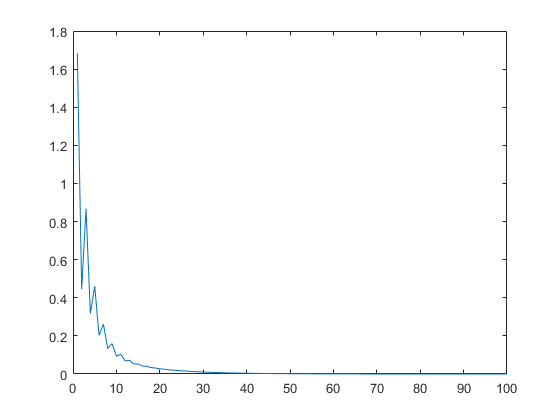


for i = 1:size(results,)
    plot(results(1,5).E(1,:))

## Testing

% % num_x_0 = 2;
% % num_real = 3;
% % num_hat = 4;
% 
% B_all = B;
% C_all = C;
% D_all = D;
% 
% % Cell of sys w/ A, B, C, D
% sys_poly.A = A_all;%= {A_all, B_all, C_all, D_all};
% sys_poly.B = B;
% sys_poly.C = C;
% sys_poly.D = D;
% 
% 
% K_all = {K};
% L_all = {L};
% 
% X_0_all = num2cell(X_0,1);
% X_hat_0_all = num2cell(X_hat_0,1);
% U_0_all = num2cell(U_0,1);
% 
% sys_real_all = PolytopicSysCalc(sys_poly, alpha_real_all);
% real_all = struct(  'alpha', num2cell(alpha_real_all,1),...
%                     'sys', sys_real_all);
% sys_hat_all = PolytopicSysCalc(sys_poly, alpha_hat_all);
% hat_all = struct(  'alpha', num2cell(alpha_hat_all,1),...
%                     'sys', sys_hat_all);
% 
% [real_grid, hat_grid, K_grid, L_grid, X_0_grid, X_hat_0_grid, U_0_grid] = ...
%     ndgrid(real_all, hat_all, K_all, L_all, X_0_all, X_hat_0_all, U_0_all);
% 
% sim_sys = struct(...
%     'alpha_real', reshape({real_grid.alpha}, size(real_grid)),...
%     'alpha_hat', reshape({hat_grid.alpha}, size(hat_grid)),...
%     'sys_real', reshape({real_grid.sys}, size(real_grid)),...
%     'sys_hat', reshape({hat_grid.sys}, size(hat_grid)),...
%     'K', K_grid,...
%     'L', L_grid,...
%     'x_0', X_0_grid,...
%     'x_hat_0', X_hat_0_grid,...
%     'u_0', U_0_grid...
%     )
% 
% sim_params.N = N;
% sim_params.u_k = @(x,K) zeros(p,1); % no control feedback
% 
% % sim_results_test = PolytopicSysSimSingle(sys_grid(1),sim_params)
% sim_results = arrayfun(@(sys) PolytopicSysSimSingle(sys, sim_params), sim_sys)
% % sim_results.sys = sys_grid(:)
% 
% 
% results =  cell2struct([struct2cell(sim_sys);struct2cell(sim_results)],...
%                         [fieldnames(sim_sys);fieldnames(sim_results)])
% 
% % sim_results = [];
% % for sys = sys_grid(:)
% %     disp(sys)
% % %     sim_results = [sim_results, PolytopicSysSimSingle(sys,sim_params)];
% % end

Note to Jonas:

- your trying to figure out how to associate alphas into the sys_grid struct.... should probbalbly give up

- once I get I'll then do the sim for a single one and apply it to all of them at once...

Yay! done!

% 
% 

NOTES for JONAS:

- you've been working and testing trying to get the cell based way to work...

- the usage of cells is great, but structs is better for some things...

- do better!!!!!

- anyway, try to get the sys and sys_all to work as a struct... 

- (sys_real.A = ;aslfdk, sys.B = a;sldkfj....

- (sys_hat.A = a;sdlfkj) etc...

Yay that's done!

% 
% 


